Daniel Sklyar

Homework 03

Exercise 2

% function called bisection_method is in function code block

Exercise 3


f = @(x) (2 .* (x .^ (3)) + 3 .* x - 1) .* cos(x) - x;
[c,n,err] = bisection_method(f,1,-1,10.^(-5),30);
fprintf('The solution is %d\n',c);

The solution is 4.385529e-01


a)

fprintf('Number iterations used %d\n',n);

Number iterations used 18


b)

fprintf('Error is %d',err(end));

Error is 7.629395e-06

 | p - p_18| < |b_14 - a_14| = 

 | 0.43856115234375 - 0.438552856445312 | = .0000152587

p_n = p + O(1/(2^n))

c)

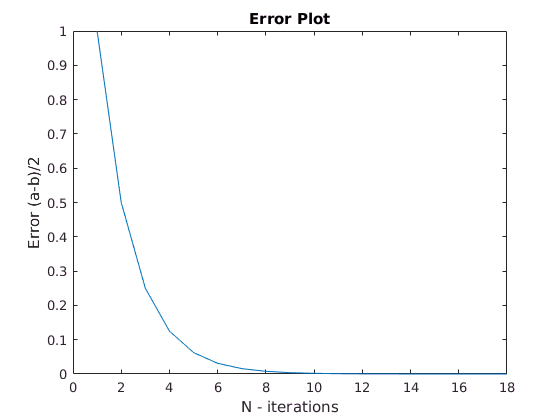

plot(1:size(err,2),err), hold on;
ylabel('Error (a-b)/2');
xlabel('N - iterations');
title('Error Plot');
hold off;

s1 = semilogy(1:size(err,2),err), hold on

s1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18]
              YData: [1 0.5000 0.2500 0.1250 0.0625 0.0312 0.0156 0.0078 0.0039 0.0020 9.7656e-04 4.8828e-04 2.4414e-04 1.2207e-04 6.1035e-05 3.0518e-05 1.5259e-05 7.6294e-06]
              ZData: [1×0 double]

  Show all properties


ylabel('Error (a-b)/2');
xlabel('N - iterations');
title('Semilogy Error Plot');
fprintf('Bisection method converges very slow with average rate of\n convergence equal to 1/2 per iteration.');

Bisection method converges very slow with average rate of
 convergence equal to 1/2 per iteration.

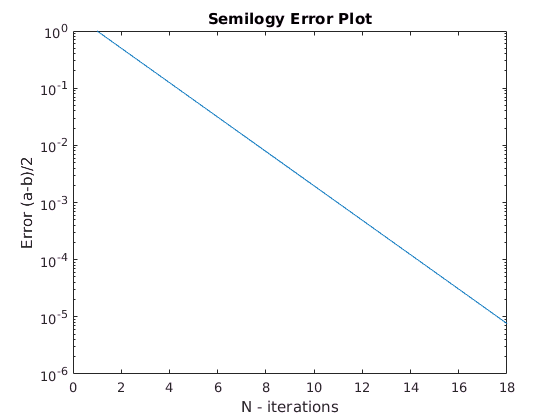

hold off;

Exercise 4

% function called fixed_point is below in function code block

Exersie 5

f = @(x) exp(-x);
initial_guess = 1;
fprintf('Initial guess used %d\n',initial_guess);

Initial guess used 1


[c,n,err] = fixed_point(f,initial_guess,10.^(-10),30);
fprintf('Number iterations used %d\n',n);

Number iterations used 30


fprintf('The solution is %d\n',c);

The solution is 5.671433e-01


Exercise 6

a)

Derivative of cos(2x) is -2sin(2x)

the local maxima is at about y = 1.99991 and about x = .7 

x = -1:.1:1;
y = -2.*sin(2.*x);
p = plot(x,y), hold on;

p =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 0.3000 0.4000 0.5000 0.6000 0.7000 0.8000 0.9000 1]
              YData: [1.8186 1.9477 1.9991 1.9709 1.8641 1.6829 1.4347 1.1293 0.7788 0.3973 0 -0.3973 -0.7788 -1.1293 -1.4347 -1.6829 -1.8641 -1.9709 -1.9991 -1.9477 -1.8186]
              ZData: [1×0 double]

  Show all properties


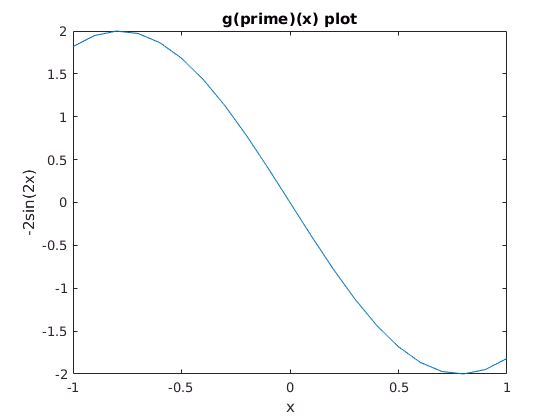

xlabel('x');
ylabel('-2sin(2x)');
title('g(prime)(x) plot');
hold off;

pks = findpeaks(y)

pks = 1.9991

syms x;
eqn = -2.*sin(2.*x) == pks;bjm,
solx = solve(eqn,x)

$$solx = \left(\begin{array}{c} -\frac{\mathrm{asin}\left(\frac{1991}{2000}\right)}{2}\\ \frac{\pi }{2}+\frac{\mathrm{asin}\left(\frac{1991}{2000}\right)}{2} \end{array}\right)$$

b)

f = @(x) cos(2.*x);
initial_guess = -1;
fprintf('Initial guess used %d\n',initial_guess);

Initial guess used -1


[c,n,err] = fixed_point(f,initial_guess,10.^(-10),100);
fprintf('Number iterations used %d\n',n);

Number iterations used 100


fprintf('The solution is %d\n',c);

The solution is 5.235284e-02


function [c,n,err] = bisection_method(f,a,b,tol,N)
    n = 1;                               % starting iteration at 1
    err = [];                            % error array init
    err(n) = (a - b) ./ 2;               % calculate the first error
    m0 = f(a);                           % set m0 to evaluated function at a
    while abs(err(n)) > tol && n < N     % if err is less than tolarance stop OR of max itr rached
        c = a + (b - a) ./ 2;            % calulate midpoint
        m = f(c);                        % evaluate f at midpoint
        if m == 0                        % if midpoint is zero stop
            break;
        end
        if m0 * m > 0                    % if f(p_n) and f(a) have same sign set a = c
            m0 = m;                
            a = c;
        else                             % else set b = c
            b = c;
        end
        n = n + 1;                       % increment N
        err(n) = (a - b) ./ 2;           % calculate err and store it
    end
end
function [c,n,err] = fixed_point(f,p0,tol,N)
    n = 1;                    % starting iteration
    c = f(p0);                % first approximation
    err = abs(c - p0);        % error calculation
    while err > tol && n < N  % if err is less than tolarance stop OR of max itr rached
        c = f(p0);            % calculate new y
        err = abs(c - p0);    % calculate new error
        n = n + 1;            % increment numb of iterations
        p0 = c;               % set p0 to a newly calculated y
    end
end